# 4.7 Design a SS controller selecting the poles using the LQR technique

load Linear_Param.mat
Cweight = [10 1 10 2]; %Most weight on theta_b, less on wheel
B1 = B(:,1);
[num,den] = ss2tf(A,B1,Cweight,0)

num =             0  -1.5948e+02  -6.9452e+02  -7.2702e+02  -7.2702e+03


den =    1.0000e+00   4.7501e+02  -6.2019e+01  -1.5371e+04            0


s = tf("s");
Nplus = num(1)*(s)^4 +num(2)*(s)^3 +num(3)*(s)^2 +num(4)*(s)^1 +num(5)*(s)^0;
Nminus = num(1)*(-s)^4 +num(2)*(-s)^3 +num(3)*(-s)^2 +num(4)*(-s)^1 +num(5)*(-s)^0;
Dplus = den(1)*(s)^4 +den(2)*(s)^3 +den(3)*(s)^2 +den(4)*(s)^1 +den(5)*(s)^0;
Dminus = den(1)*(-s)^4 +den(2)*(-s)^3 +den(3)*(-s)^2 +den(4)*(-s)^1 +den(5)*(-s)^0;
sysGG = Nplus*Nminus/(Dplus*Dminus)

sysGG =
 
  -2.543e04 s^6 + 2.505e05 s^4 + 9.57e06 s^2 + 5.286e07
  -----------------------------------------------------
    s^8 - 2.258e05 s^6 + 1.461e07 s^4 - 2.363e08 s^2
 
Continuous-time transfer function.
Model Properties


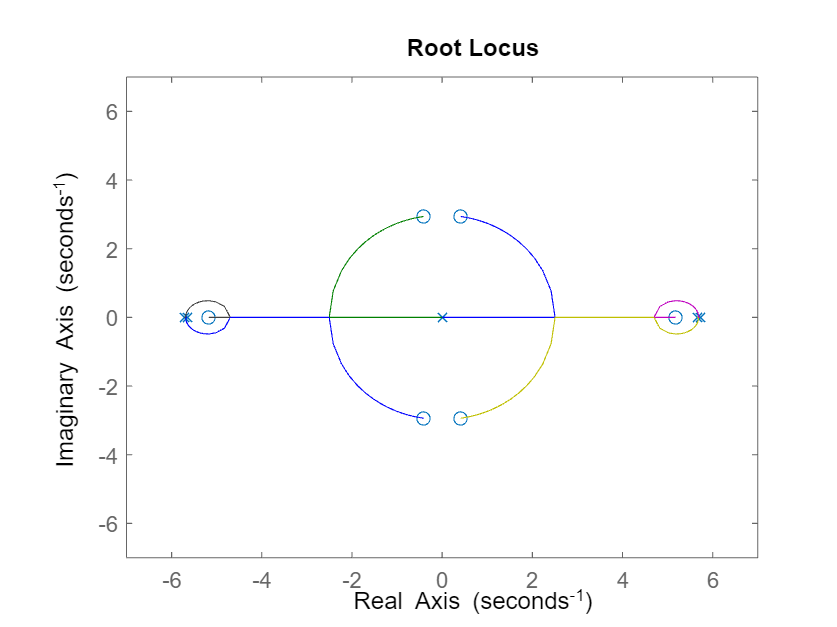



rlocus(sysGG)
% xaxis(-7,7)
xlim([-7 7])
% yaxis(-7,7)
ylim([-7 7])

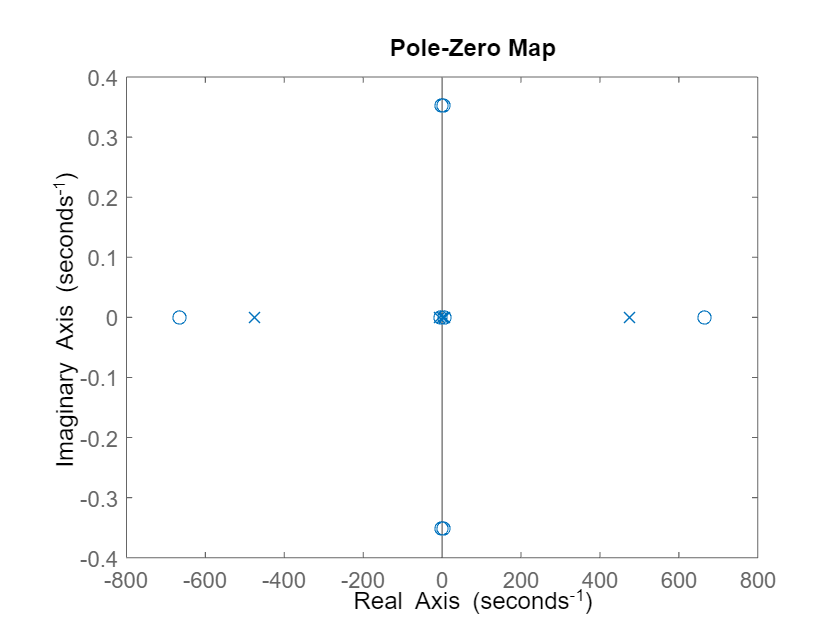

rhoChose = 8.5;
  pzmap(1+rhoChose*sysGG)

poles =  zero(1+rhoChose*sysGG);
format shortE
stablePoles = poles(real(poles)<0)

stablePoles =   -6.6476e+02 + 0.0000e+00i
  -5.0809e+00 + 0.0000e+00i
  -2.4802e+00 + 3.5205e-01i
  -2.4802e+00 - 3.5205e-01i


K = acker(A,B1,stablePoles)

K =   -2.9155e+01  -4.9970e+01  -8.1847e+01  -1.3640e+01


poles = stablePoles;
save("poles.mat","poles")

%Testing to see right K achieved
Q = rhoChose*Cweight'*Cweight

Q =    8.5000e+02   8.5000e+01   8.5000e+02   1.7000e+02
   8.5000e+01   8.5000e+00   8.5000e+01   1.7000e+01
   8.5000e+02   8.5000e+01   8.5000e+02   1.7000e+02
   1.7000e+02   1.7000e+01   1.7000e+02   3.4000e+01


R = 1

R =      1


K = lqr(A,B1,Q,R)

K =   -2.9155e+01  -4.9970e+01  -8.1847e+01  -1.3640e+01



Q = zeros(4);
Q(1,1) = 1/0.05^2;
Q(2,2) = 0;
Q(3,3) = 1/0.5^2

Q =    4.0000e+02            0            0            0
            0            0            0            0
            0            0   4.0000e+00            0
            0            0            0            0


Q(4,4) = Q(3,3)

Q =    4.0000e+02            0            0            0
            0            0            0            0
            0            0   4.0000e+00            0
            0            0            0   4.0000e+00


R = 1/8^2

R =    1.5625e-02


K = lqr(A,B1,Q,R)

K =   -1.6000e+02  -1.1399e+02  -2.0696e+02  -3.7736e+01
